**Module UE 913 - Systèmes de Navigation (M2 E3A SAM)**

**Exploitation de données GPS**

**TP2 MATLAB – 4h**

**Auteur et responsable de module : Naima AITOUFROUKH-MAMMAR**

**Fait par:**

- **BELLAHCENE Kheir Eddine **

- **GEROL Logan**

**    Promotion 2023 - 2024 **

## `1. Explication du code NMEA`

`Expliquer brièvement le code NMEA et plus particulièrement les phrases ayant les préfixes suivants :`

Le code NMEA est un standard défini uniquement comme étant le protocole de transmission des données entre les instruments et équipements électroniques liés au GPS. Les données sont transmises sous forme de trames de données où chaque trame commence par le caractère $ suivi par un groupe de 2 lettres pour l'identifiant du récepteur 

**GP** pour Global Positioning System. 

- `$GPGGA`` : `Fournit des informations sur le fix GPS et la date. Les données incluent la latitude, la longitude, la qualité du fix, le nombre de satellites utilisés, la hauteur géoïde et d'autres informations liées à la position.

- `$GPGLL : `Fournit des informations de position géographique sous la forme de longitude et latitude.

- `$GPVTG : ` Donne la direction (**cap**) et la vitesse de déplacement. La vitesse est généralement fournie en nœuds et kilomètres par heure.

- `$GPZDA : `Fournit la date en format **UTC** (Coordinated Universal Time), ainsi que le décalage de la zone de temps et l'heure locale.

- `$SDDBS : ``D`onnées du sondeur.

Suivent ensuite un certain nombre de champs séparés par une "virgule". Le rôle de la virgule est d'être le séparateur de champs, qui permet la déconcaténation des données dans le programme de traitement des données.

## `2. Extraction de la longitude et latitude`

- `Charger le fichier "nmealineread.m" de Ecampus et le sauvegarder dans votre répertoire accessible à MATLAB. `

- `Expliquer le fonctionnement de la fonction, préciser la grandeur de sortie et sa structure. `

- `Tester la fonction sur la ligne suivante: $GPGGA,074259.000,4846.9098,N,00205.9515,E,1,10,0.9,199.0,M,,,,0000*02`

[data,ierr] = nmealineread('$GPGGA,074259.000,4846.9098,N,00205.9515,E,1,10,0.9,199.0,M,,,,0000*02')

data = struct with fields:
     BODCTime: 0.3215
     latitude: 48.7818
    longitude: 2.0992


ierr = 0

La fonction :

 **nmealineread** :  prend pour argument la trame envoyée par le satellite et retourne deux informations qui sont : 1. la data qui regroupe les informations de la : **latitude**, la **longitude** et le **temps** ; le tous dans une structure de code d'erreur et d'un vecteur 3x1.

Le temps représente un pourcentage d'une journée de **24h, ierr **qui spécifie le code de l'erreur rencontré lors du traitement.

si **ierr**:

- **ierr = -2:** La chaine de caractère **NMEA **(Trame)  reconnue mais la fonction n'est pas capable de l'ouvrir.

- **ierr = -1: **La chaine de caractère **NMEA **non reconnue.

- **ierr = 0: **Pas d'erreur.

 Pour ce type de Trame **$GPGGA.**

### `2.1 Extraction des données d'un itinéraire`

- `Charger les fichiers d'itinéraire sur Ecampus: ``GPGGA-PARIS-LIVIC.nmea`` et ``circuit.nmea`` et le sauvegarder dans répertoire accessible à MATLAB.`

- `Analyser le script matlab permetttant d'obtenir les deux vecteurs de longitude et de latitude de l'itinéraire. (Celui-ci est fourni dans la fonction trace-trace.m).`

**Lecture de données GPS depuis un fichier** :

- Le code ouvre un fichier texte ('GPGGA-PARIS-LIVIC.txt') qui contient des données au format NMEA, en particulier des phrases GPGGA (contenant des informations de latitude et de longitude).

- Il lit le fichier ligne par ligne et extrait les informations de latitude et de longitude pour les phrases GPGGA.

- initialise **longitude** **latitude **à  des vecteurs vide et un **n** à zero 

- Ensuite il vérifier si la trame elle est bonne si elle commence par **$ **sinon il fait un **break **et il sort de while.

- Après il compare si les 6 premier chaine de carcatère sont égale à **'$GPGGA' **si il a testé que c'est la bonne trame il récupère la **longitude** et la **latitude **dans les vecteurs vide intialiser prècedement est il incrémente **n++ **pour compter le nombre trame dans le fichier.

Écriture des données au format KML :

- Le code utilise une fonction appelée `kmlwrite` pour écrire les données de latitude et de longitude dans un fichier au format KML .

kmlwrite(**'GPGGA-PARIS-LIVIC'**,latitude,longitude)

En donnat à la fonction kmlwrite le nom de fichier en sortie **'GPGGA-PARIS-LIVIC' **et les vecteurs contenant latitude et longitude comme arguments d'entrée à la fonction.

Ensuite faire une conversion des trois points donées en coordonées **Lambert** qui sont un système de coordonnées cartésiennes utilisé principalement en France pour la cartographie pour les points (48.782211, 2.242899), (48.779270, 2.199297) et (48.816359, 2.279649) en utilsant la fonction **lat_long_lamb **définit et implémenté dans ce code trace_trace.m et qui permets de faire la conversion en lambert. Enfin tracer ces trois points spécifique en *****

**Pour Lire, convertir en Lambert et tracer 'GPGGA-PARIS-LIVIC.txt'**

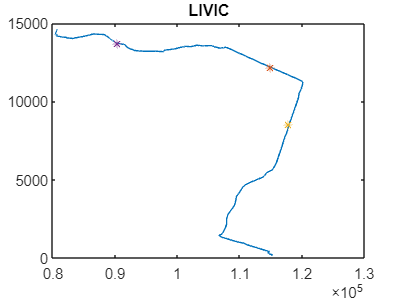

figure(1)
[longitude,latitude,X,Y] = trace_trace; 
title('LIVIC')

- `Tracer l'itinéraire et le vérifier sur googlemap. Isoler une section de l'itinéraire.`

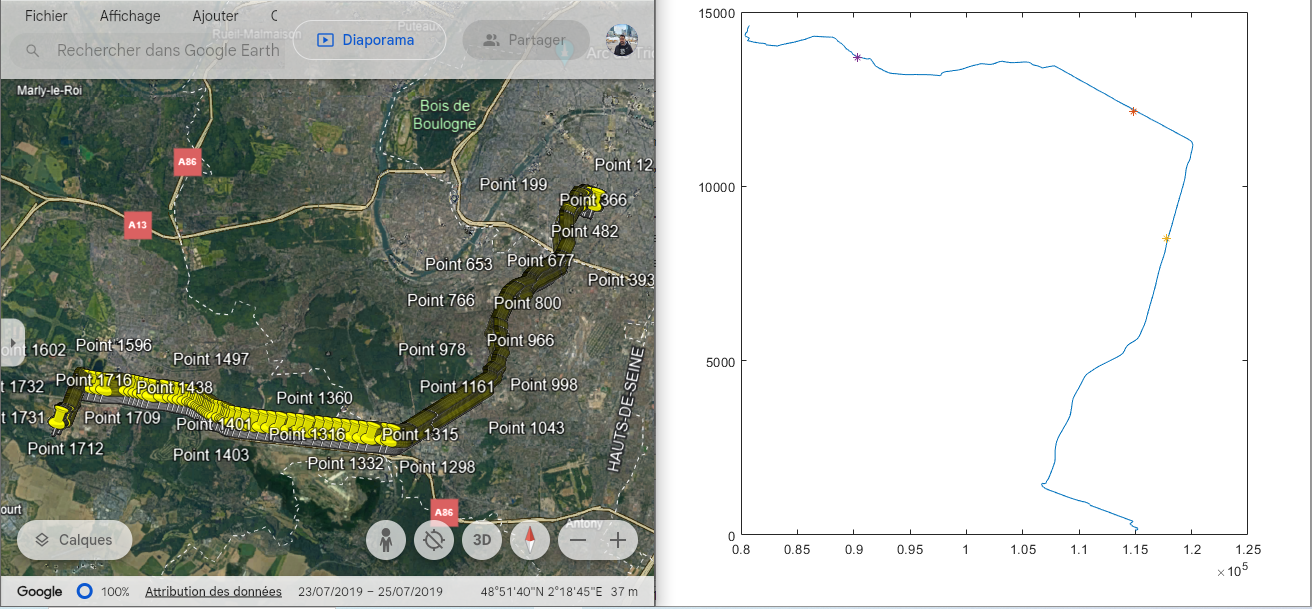

Pour tracer le circuit pelvoux contenu dans circuit.nmea lire ces trames et les converitr en Lambert ainsi que tracer des points spécifique autour pelvoux et de générer un fichier kml pour vérifir sur googl earth en suite.

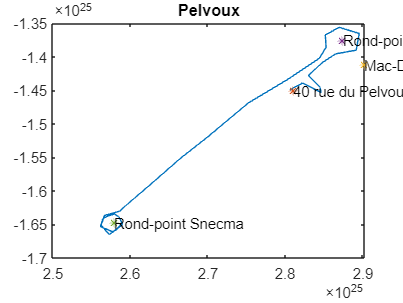

figure(2)
[latitude,longitude,X,Y]=trace_trace_pelvoux;
title('Pelvoux')

### 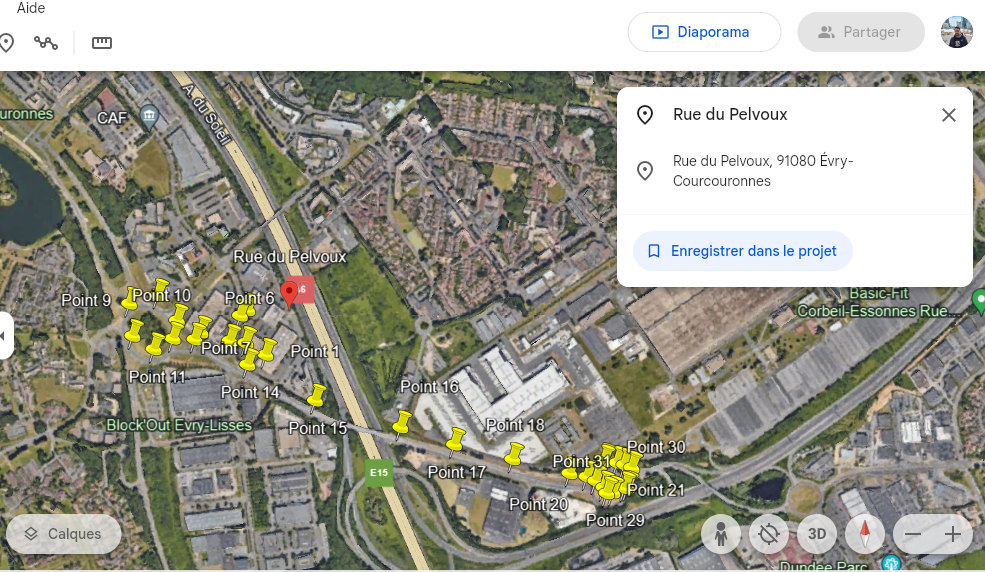

**Commentaire****:**

On voit bien que l'itinéraire tracé à l'aide des 2 vecteurs long_lat reproduisent la meme chose que la vérité terrain. 

### `2.2 Projection en coordonnées Lambert 93`

- `Expliquer le système de coordonnées Lambert 93 `

 La projection conique conforme de Lambert est une projection conique. Tous les méridiens sont des lignes droites équidistantes convergeant vers un point commun, qui est le pôle le plus proche des parallèles de référence. Les parallèles sont représentés sous forme d’arcs circulaires centrés sur le pôle. Leur espacement augmente avec l’éloignement à partir des parallèles de référence. L’autre pole eest donc applati. Lorsque les parallèles de référence sont définis dans l’hémisphère nord, la forme en éventail du graticule est orientée vers le haut ; lorsque les parallèles de références se trouvent dans l’hémisphère sud, la forme en éventail du graticule est orientée vers le bas. Le graticule est symétrique sur le méridien central Les paramètres **1SP** conique conforme de Lambert sont les suivants :

                    • Constante en **X **

                    • Constante en **Y**

                    • Méridien central 

                    • Facteur d'échelle 

                    • Latitude de l’origine

 Les paramètres** 2SP** conique conforme de Lambert sont les suivants :

                    • Constante en X

                    • Constante en Y 

                    • Méridien central 

                    • Parallèle de référence 1 

                    • Parallèle de référence 2 

                    • Latitude de l’origine 

- `Retrouver les formules de conversion Longitude/Latitude vers Lambert 93`

$\lambda_0$`=3deg`

$\phi_0$`=46.5deg`

$\phi_1$`=44deg`

`$\phi_2=49deg`


$$X_0 = 700000$$



$$Y_0=6600000$$



$$a=6378137$$



$$e=0.06$$


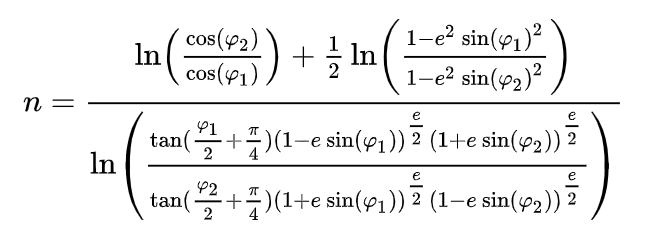

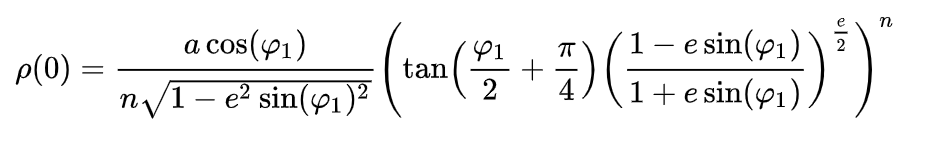

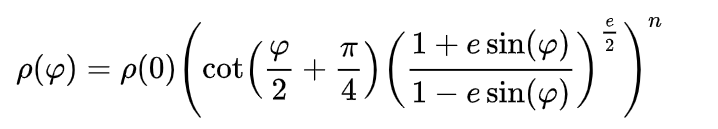

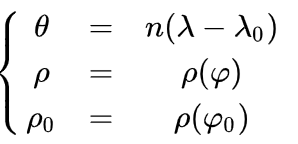

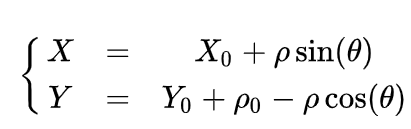

- `Analyser le programme comportant les formules pour obtenir les deux vecteurs de coordonnées X et Y. Tracer la trace de l'itinéraire. `

Le code fourni est une fonction MATLAB qui effectue la conversion des coordonnées géographiques (latitude et longitude) en coordonnées cartésiennes du système de projection Lambert 93 en France. Voici une analyse du code :

- Paramètres de la projection Lambert 93 :

- `lam0`**, **`phi0`**, **`phi1`**, **`phi2` : Ces variables représentent les paramètres de la projection **Lambert 93**, notamment la longitude du méridien d'origine (`lam0`), la latitude d'origine (`phi0`), et les latitudes standard (`phi1`** et **`phi2`).

- Coordonnées d'origine et paramètres de la Terre :

- `X0`** et **`Y0` : Coordonnées du point d'origine en Lambert 93.

- `a` : Rayon équatorial de la Terre.

- `e` : Excentricité de l'ellipsoïde terrestre.

- Calcul de paramètres liés à la projection :

- `n1` et `n2` : Paramètres utilisés dans le calcul de la valeur de `n`, qui est une constante de la projection.

- `rho0` : Calcul de la valeur de `ro0` utilisée dans le calcul ultérieur.

- Conversion des coordonnées géographiques en **Lambert 93 **:

- La fonction prend en entrée la latitude (`latitude`) et la longitude (`longitude`) en degrés et effectue une série de calculs pour obtenir les coordonnées **Lambert 93 **en mètres (`X`** et **`Y`).

- Calcul des coordonnées** Lambert 93** :

- `theta` : Calcul de l'angle `theta` utilisé dans la formule de conversion.

- `rho` : Calcul de la distance `ro` utilisée dans la formule de conversion.

- `X` et `Y` : Coordonnées Lambert 93 finales obtenues à partir des calculs précédents.

- `Vérifier la projection des points de (latitude,longitude) = (48.779270, 2.199297), (48.782211, 2.242899) et (48.816359, 2.279649) sur la trace. `

On définit ainsi deux intersections 1 (sur le côté Nord de coordonnée** Y = 6660000**) et 2 (sur le côté Ouest de coordonnées **X = 443000**) qui vont donner les coordonnées **Lambert-93** du point **M**. La coordonnée **X** du site est égale à la somme de la coordonnée **X** de **C** et de la distance entre **C **et** 1**.

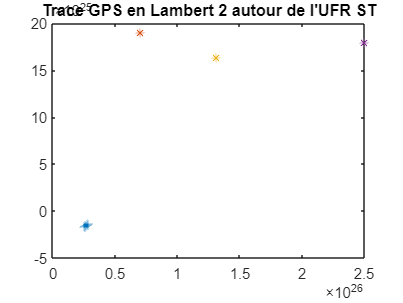

[X1,Y1]=lat_long_lamb2(latitude,longitude);
[P1_X,P1_Y]=lat_long_lamb2(48.779270, 2.199297);
[P2_X,P2_Y]=lat_long_lamb2(48.782211, 2.242899);
[P3_X,P3_Y]=lat_long_lamb2(48.816359, 2.279649);
figure(3)
plot(X1,Y1,'+',P1_X,P1_Y,'*',P2_X,P2_Y,'*',P3_X,P3_Y,'*')
title("Trace GPS en Lambert 2 autour de l'UFR ST")


%% Déclaration des latitudes et logitude 
latt=[48.816359 48.782211 48.779270];
longg=[2.279649 2.242899 2.199297];
kmlwrite("Points",latt,longg)

## 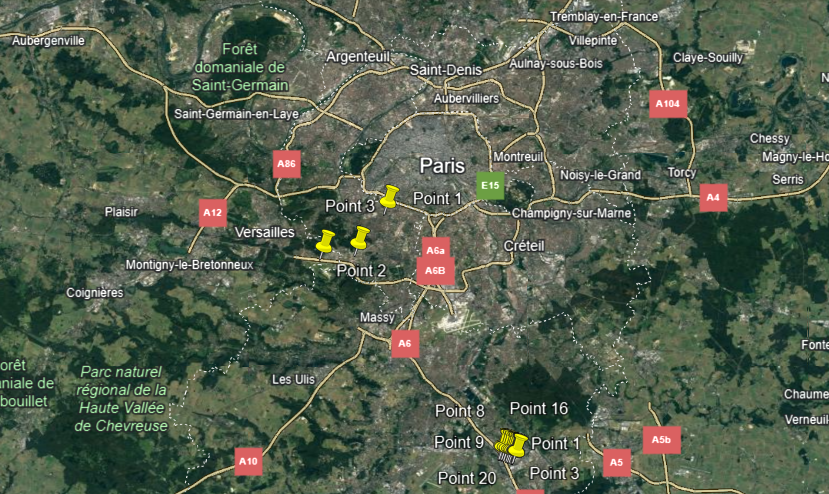

**Commentaire**:

Après avoir projeté les 3 points demandés, on voit bien qu'ils sont bien éloignés du chemin de pelvoux et la projection de ces derniers sur google earth confirme bien notre projection.

## `3. Fusion multi-capteurs : GPS - Odométrie`

### `3.1 Problématique`

`Différentes techniques de positionnement par GPS existent et offrent aujourd'hui une précision suffisante pour de nombreuses applications (guidage, information aux automobilistes,...). Les techniques de type DGPS et RTK offrent une grande précision et permettent la mise en oeuvre d'application de controle automatique des véhicules. Néanmoins, la localisation par GPS souffre de problèmes de masquage (perte de signal, dégradation de la précision) notamment lors de passage sous un pont, dans un tunnel ou pour des raison de multi-trajets en urbain. De plus, le GPS est dit dans des conditions de visibilité satellitaire réduite dès lors que moins de 4 satellites sont visibles L'objet de la programmation est d'utiliser les autres capteurs dont dispose le véhicule, notamment les odomètres, équipant en standard tous les véhicules munis d'un ABS. On remplace alors durant la durée de masquage (ou de dégradation du signal) le positionnement par celui de ces capteurs et on améliore de façon globale la précision et la fiabilité.`

### `3.2 Architecture de fusion`

`Le schéma de l'algorithme de fusion fait appel à un filtre de Kalman étendu (Extended Kalman Filter) de la figure ci-dessous. Les capteurs ABS des deux roures arrières (droite et gauche) fournissent des déplacements élémentaires (capteur à effet Hall), convertis translation et rotation angulaire du véhicule. Les données ``GPS`` ainsi que le vecteur de mesures inertielle ``U`` sont alors combinées dans le filtre EKF pour fournir positionnement en ``x`` et ``y`` ainsi que l'orientation du véhicule.`

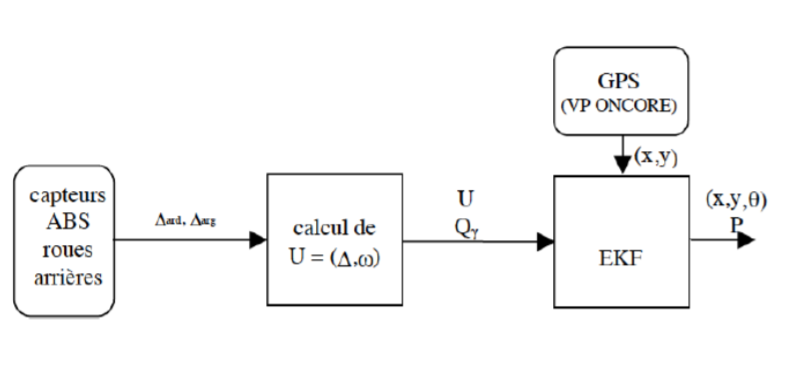

### `3.3 Modèle cinématique du véhicule`

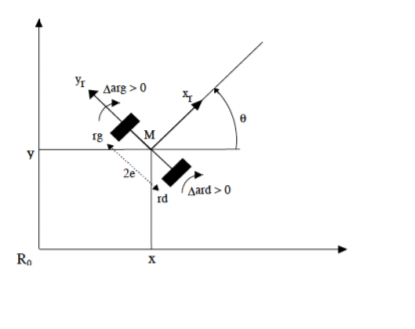

`Le modèle de la cinématique du point `$M$` de la figure ci-dessus est donné par`


$$\left\{ 
\begin{array}{c}
x_{i+1}=x_{i}+\Delta _{i}\cos \left( \theta _{i}+\frac{\omega _{i}}{2}\right)
\\ 
y_{i+1}=y_{i}+\Delta _{i}\sin \left( \theta _{i}+\frac{\omega _{i}}{2}\right)
\\ 
\theta _{i+1}=\theta _{i}+\omega _{i}%
\end{array}%
\right.$$


`où `$\Delta_{i}$` la translation élémentaire de la roue et `$\omega_{i}$` la rotation élémentaire. Notons que le déplacement élémentaire est obtenue à partir de la rotation `$\omega _{i}$` en multipliant par le rayon de courbure.`

`Le système est sous la forme non-linéaire `


$$X_{i+1}=f\left( X_{i},U_{i}\right)
$$


`avec `$X_{i}=\left[ 
\begin{array}{c}
x_{i} \\ 
y_{i} \\ 
\theta _{i}%
\end{array}%
\right]$`, `$U_{i}=\left[ 
\begin{array}{c}
\Delta _{i} \\ 
\omega _{i}%
\end{array}%
\right]$ `et `$\left\{ 
\begin{array}{c}
\Delta _{i}=\frac{\Delta ard_{i}+\Delta \arg _{i}}{2} \\ 
\omega _{i}=\frac{\Delta ard_{i}-\Delta \arg _{i}}{2e}%
\end{array}%
\right.
$

`où `$e$` est la longueur de la voie (essieu arrière).`

`Dans ces équations, la mesure est prise par le capteur ABS sur chacune des roues arrières et les calculs sont réalisés sous les hypothèses suivants : Le centre de l'essieu est noté $M$. Il est lié au véhicule que l'on cherche à localiser. Ce point remarquable se situe sur la droite reliant les points de contact des roues avec le sol. Ces contacts avec le sol, s'il n'y a ni patinage ni dérapage (c'est-à-dire pas de glissement), font que la vitesse du point `$M$` est perpendiculaire à l'axe reliant les deux roues, et portée par l'axe `$(M,x_r)$`.`

### `3.4 Equations du positionnement GPS`

`Pour ce qui est du GPS, on suppose que l'antenne du ré``cepteur`` se situe à la verticale du point M. On utilise le GPS comme capteur de position et on n'utilise pas la mesure de vitesse qu'il fournit. Dans ce cas, le mod``èle d'observation est le suivant :`


$$\left[ 
\begin{array}{c}
x_{GPS} \\ 
y_{GPS}%
\end{array}%
\right] =\left[ 
\begin{array}{ccc}
1 & 0 & 0 \\ 
0 & 1 & 0%
\end{array}%
\right] \left[ 
\begin{array}{c}
x \\ 
y \\ 
\theta
\end{array}%
\right]$$


`Cette mesure est de la forme `


$$Z_{j}=CX_{j}

$$


`On remarquera les indices `$i$ et $j$` diffèrent du fait d'une vitesse de rafraichissement du système ABS plus élevée. Ainsi les mesures odométriques sont acquises à 50Hz et les mesures GPS sont acquises à 1Hz.`

### `3.5 Modèles des bruits`

`Dans le cadre de l'estimation stochastique, on considère que le modèle, l'entrée et la mesure sont affectées par des bruits : `


$$\left\{ 
\begin{array}{c}
X_{i+1}=f\left( X_{i},U_{i}\right) +\alpha _{i} \\ 
U_{i}=\left( U_{i}\right) _{vrai}+\beta _{i} \\ 
Z_{j}=CX_{j}+\gamma _{j}%
\end{array}%
\right.$$


`Chacun des bruits `$\alpha _{i}$`, `$\beta _{i}$` et `$\gamma _{i}$` dispose d'une matrice de Covariance à déterminer. Elles seront notées : `$Q_{\alpha }$`, `$Q_{\beta }$` et `$Q_{\gamma }$`. Nous avons : `


$$U_{i}=\left[ 
\begin{array}{cc}
1/2 & 1/2 \\ 
1/(2e) & -1/(2e)%
\end{array}%
\right] \left[ 
\begin{array}{c}
\Delta ard_{i} \\ 
\Delta arg_{i}%
\end{array}%
\right] =M\left[ 
\begin{array}{c}
\Delta ard_{i} \\ 
\Delta arg_{i}%
\end{array}%
\right]
$$


`En notant `$Q_{ABS}$` la variance scalaire de l'erreur de mesure d'un capteur ABS, on obtient : `


$$Q_{\alpha }=M\left[ 
\begin{array}{cc}
Q_{ABS} & 0 \\ 
0 & Q_{ABS}%
\end{array}%
\right] M^{T}$$


### `3.6 Linéarisation du modèle`

`Le filtre de Kalman utilise deux étapes principales :`

- `au pas `$i$`, la prédiction `$X_{i+1/i}$` de l'état à partir de l'état estimé `$X_{i.i}$

- `au pas `$\left( i+1\right)$`, on corrige la prédiction pour obtenir l'estimation `$X_{i+1/i+1}$

`On itère par la suite le processus.`

`Le filtre de Kalman étendu utilise un modèle liné``airisé ``autour des variables ``estimé``es : `$\hat{X}_{i/i}=\left[ 
\begin{array}{c}
\hat{x}_{i/i} \\ 
\hat{y}_{i/i} \\ 
\hat{\theta}_{i/i}%
\end{array}%
\right]$.$\left\{ 
\begin{array}{c}
x_{i+1}=x_{i}+\Delta _{i}\cos \left( \theta _{i}+\frac{\omega _{i}}{2}\right)
\\ 
y_{i+1}=y_{i}+\Delta _{i}\sin \left( \theta _{i}+\frac{\omega _{i}}{2}\right)
\\ 
\theta _{i+1}=\theta _{i}+\omega _{i}%
\end{array}%
\right.$


$$A_{i} =\frac{\partial f}{\partial X}\left( \hat{X}_{i/i},U_{i}\right) =%
\left[ 
\begin{array}{ccc}
1 & 0 & -\Delta _{i}\sin \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}%
\right) \\ 
0 & 1 & \Delta _{i}\cos \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}%
\right) \\ 
0 & 0 & 1%
\end{array}%
\right] \\
B_{i} =\frac{\partial f}{\partial U}\left( \hat{X}_{i/i},U_{i}\right) =%
\left[ 
\begin{array}{cc}
\cos \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}\right) & -\frac{\Delta
_{i}}{2}\sin \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}\right) \\ 
\sin \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}\right) & \frac{\Delta
_{i}}{2}\cos \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}\right) \\ 
0 & 1%
\end{array}%
\right]$$


`Les équations du filtres sont les suivantes :`

- `Prédiction sans mesure extéroceptive (GPS)`


$$\hat{X}_{i+1/i}=f\left( \hat{X}_{i-1/i},U_{i}\right)$$


`On remarque qu'on itère plusieurs fois l'étape de prédiction.`

- `Prédiction avec mesure GPS `$\left( i=j\right)$


$$\hat{X}_{i+1/i}=f\left( \hat{X}_{i/i},U_{i}\right)
$$


- `Mise à jour de la matrice de variance de l'erreur de prédiction `


$$P_{i+1/i}=A_{i}P_{i/i}A_{i}^{T}+B_{i}Q_{\gamma }B_{i}^{T}+Q_{\alpha }
$$


- `Etape`` de recalage (estimation). On utilise la mesure GPS `$Z_{j}$` qui apparaît à l'instant `$j$`. On a : `$\hat{X}_{j/j-1}=\hat{X}_{i+1/i}$ `et `$P_{j/j-1}=P_{i+1/i}$


$$\hat{X}_{j/j}=\hat{X}_{j/j-1}+K_{j}\left( Z_{j}-C\hat{X}_{j/j-1}\right)$$


`Le gain de Kalman étant préalablement calculé par `


$$K_{j}=P_{j/j-1}C^{T}\left( CP_{j/j-1}C^{T}+Q_{\beta }\right) ^{-1}$$


`On peut déterminer la matrice de covariance de l'erreur d'estimation par :`


$$P_{j/j}=\left( I_{3}-K_{j}C_{{}}\right) P_{j/j-1}
$$


`La matrice `$C$` est supposée constante, il suffira de remplacer `$C$` par `$C_{j}$` dans le cas où elle est variable.`

### `3.6 Travail à réaliser`

`Afin de faciliter le travail en séance, un certain nombre d'éléments vous sont fournis :`

- `Un fichier de mesures`

- `Un programme de fusion par filtrage de Kalman`

- `Un programme MATLAB de visualisation des résultats de la fusion`

- `datasi.mat`` fichier de données réelles au format matlab`

- `fusion_gps_odo.m`` programme principal`

- `entree_odo_ar.m`` sous programme calculant l'entrée U de l'EKF`

- `visualisation.m`` programme de visualisation des résultats`

- `trouve_indice.m`` sous programme de "``visualisation.m``"`

- `ellipse.m`` sous programme traçant des ellipses d'incertitude`

- `Charger le fichier de mesures et commentez la structure et les données enregistrées.`

- `Exécuter et commenter les programmes et les résultats. Changer les durées de masquages et évaluer les performances du filtre en faisant varier les variances des bruits.`

- `Remplacer la mesure de la vitesse de rotation de lacet `$\omega$` calculée à partir du capteur ABS par la mesure fournie par le gyroscope.`

- `Reprogrammer le filtre et comparer les résultats obtenus.`

    L'objectif de cette partie et faire de la fusionner multi-capteurs à partir de plusieurs source de mesure afin d'obtenir une estimation fiable et robuste aux erreurs de modélisation et de mesures du notre système, et pour cela on a effectué deux architecture de fusion (GPS + ABS) et (GPS + IMU). En utilisant l'algorithme d'estimation filtre de kalman étendu.

Dans un premier temps on a modélisé notre modèle de véhicule par un modelé a deux roues non-linéaire en ajoutant des erreur en niveau de modélisation, vecteur de commande, et le vecteur de mesure par des bruit blanc gaussien.

Le filtre de kalman étendu se déroule dans deux étapes principale, dans un premier temps il fait de la prédiction tout en linéarisant notre modèle non-linéaire a chaque pas d'échantillonnage en calculant les matrice A, B . Puis on fais la prédiction on utilisant l'odométrie dans ce travaille on va utiliser deux source d'odométrie le capteur ABS et une centrale IMU, afin de comparer les résultats . Dans la deuxième partie du filtre on va corriger notre prédiction à travers une mesure extéroceptive dans notre cas c'est bien le GPS, c'est l'étape de mise à jour de notre états. 

3.2 dans cette partie on fusionne la mesure de GPS avec l'ABS, tout en masquant l'information du GPS, et faire varie la matrice de variances des bruits.

- Résultats obtenue sans masquage de l'information du GPS.

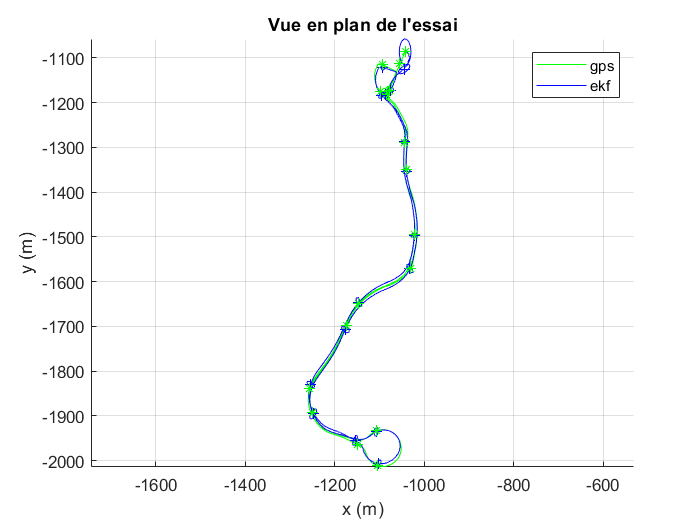

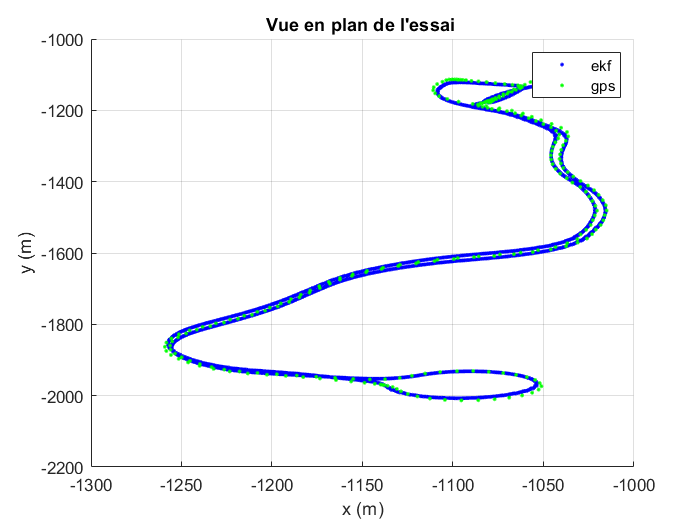

On voit bien que que l'estimation par le filtre de kalman étendu ne donne est une bonne estimation de vecteur d'état x, y. ce qui confondu avec notre mesure externe GPS. Ainsi que on ne voit pas les ellipsoïdes des incertitudes ce qui ne signifie que notre estimation est bonne.

- Cas d'un masquage de données du GPS dans deux plages.

masque=[100,150

200,250];

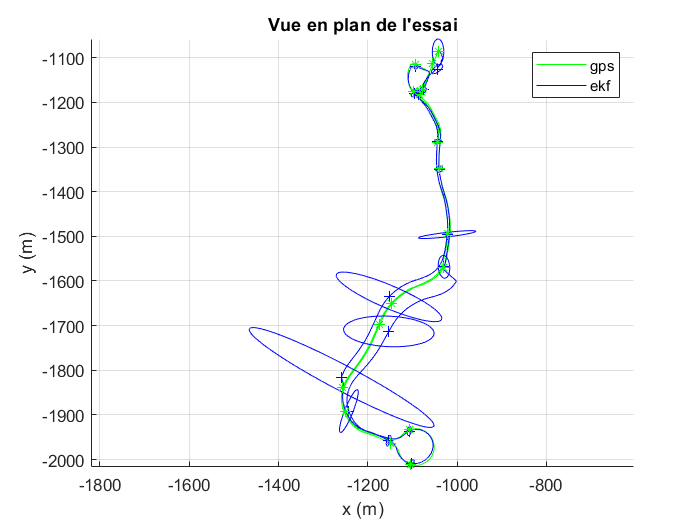

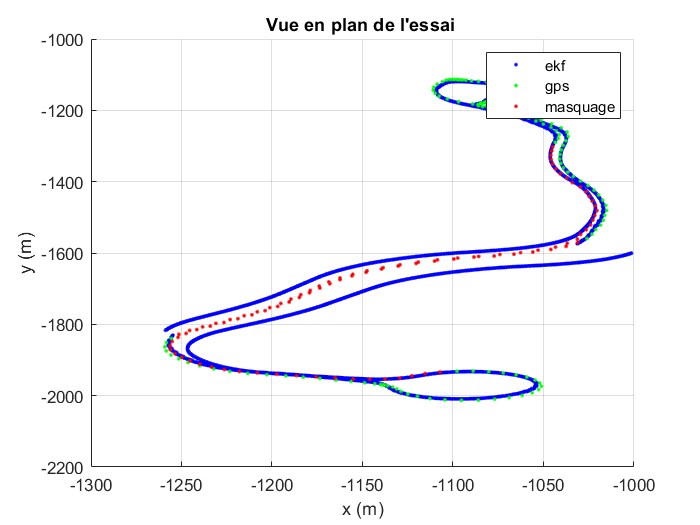

dans le cas d'absence de l'information du GPS dans intervalle de temps considérable on remarque de choses important, la première du chose notre algorithme d'estimation continue à faire du prédiction et se diverge pus lors de l'absence du données du GPS sur la trajectoire de référence que on obtient lors de y a pas de masquage et ça due au accumulation des erreurs du capteur ABS qui contient du bais sue au phénomène de glissement des roues, la deuxième chose qui est remarquable l'algorithme d'estimation est globalement asymptotiquement stable est localement exponentielle stable quelle que soit l'état de notre trajectoire des que l'information de GPS revient l'algorithme converge, ainsi que l'ellipsoïde de l'incertitude ayant un rayon petit lors de l'absence de l'information mais au fur et à mesure on avance et l'information du GPS est absente le rayon de l'ellipsoïde augmente.

- Augmentation du bruit en variant la matrice de covariance.

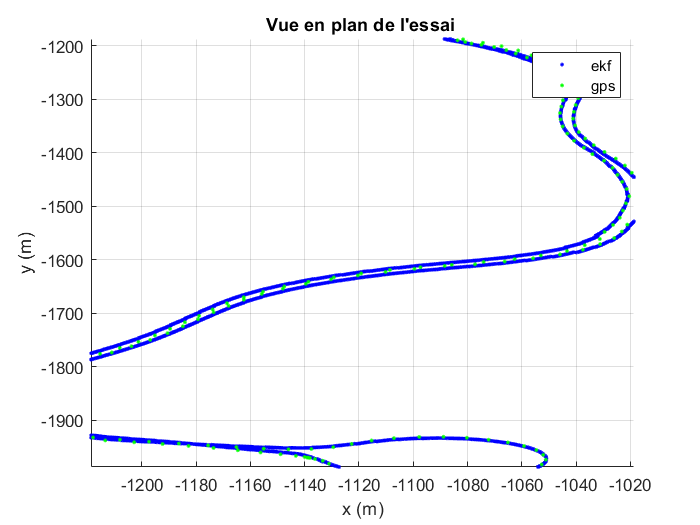

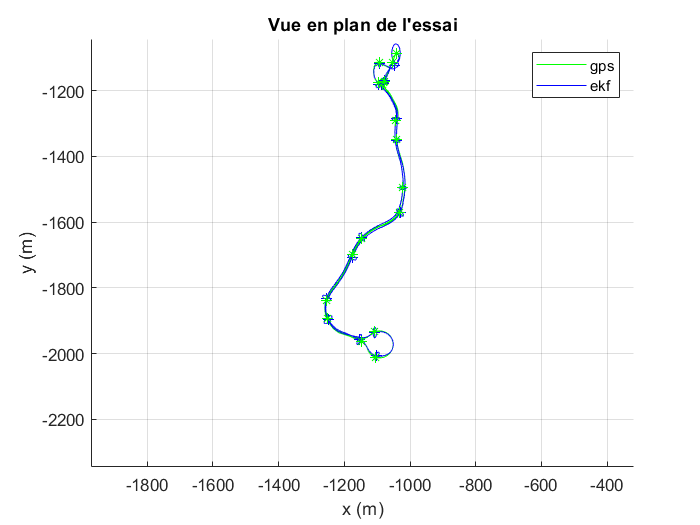

Lorsque on augmente le bruit dans le capteur ABS et sans masquage de l'information du GPS on voit bien que le nombre d'ellipsoïde augmente ce qui signifie on est toujours incertain dans notre mesure mais notre incertitude est bien borné par l'ellipsoïde en x et y, mais on aura toujours une bonne estimation parce que on Save bien que notre erreur et autour d'un certain intervalle.

3.

Dans cette partie on veut remplacer la mesure de w calculer par la déférence de déplacement de capteur ABS par la donnée de rotation suivant l'axe Z du gyroscope. Et pour faire ca on a modifier le fichier 'entree_odom_ar.m' au lieu de calculer w a partir des structure data des mesure de odom on a utilisé data.ins.guro_z .

% w=(delta_ard(i)-delta_arg(i))/(2*e);

w = data.ins.gyro_z(i) ;

4. 

Maintenant on va examiner notre estimateur en utilisant la donnée du centrale inertielle pour la rotation suivant l'axe orthogonal w. en effectue cette configuration on obtient les résultats suivants : 

 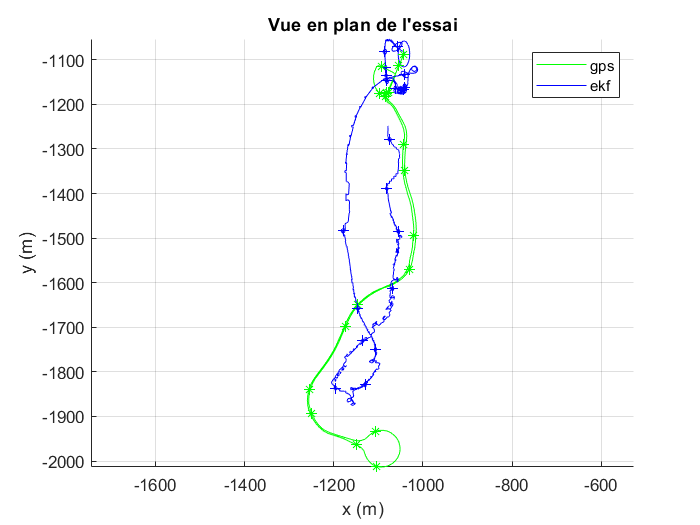

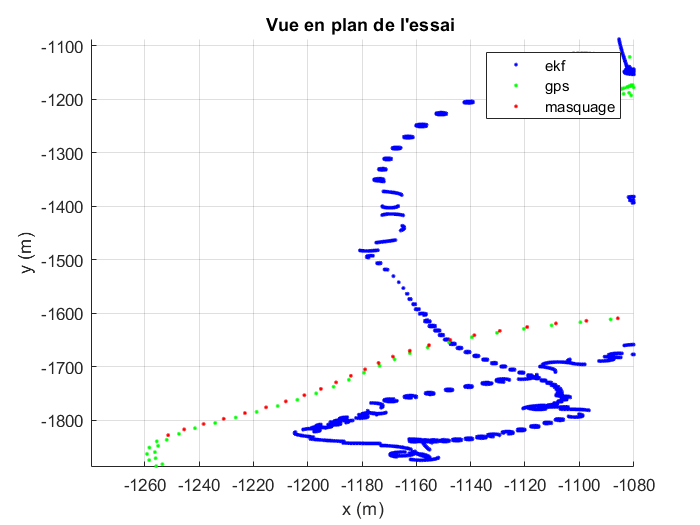

On constate que notre trajectoire finale est décalée ca est due erreur d'intégration de la vitesse angulaire gyroscopique qui nous a décalé en coordonnée, due au l'absence de l'information du GPS et de l'accumulation d'erreur d’intégration a chaque pas d'échantillonnage.

## `Annexes `

## `Transformation Latitude longitude vers Lambert 93`

`Cette fonction transforme directement des vecteurs de positionement en latitude et longitude, donnés en degrés en deux vecteurs X et Y de coordonnées en Lambert 93. Pour pouvoir appliquer le formules, tous les angles sont convertis en radians`

$\lambda_0$`=3deg`

$\phi_0$`=46.5deg`

$\phi_1$`=44deg`

`$\phi_2=49deg`


$$X_0 = 700000$$



$$Y_0=6600000$$



$$a=6378137$$



$$e=0.06$$


function [X,Y]=lat_long_lamb2(latitude,longitude);
lam0=3/180*pi;
phi0=46.5/180*pi;
phi1=44/180*pi;
phi2=49/180*pi;
X0 = 700000;
Y0=6600000;
a=6378137;
e=0.06;
n1=log(cos(phi2)/cos(phi1))+1/2*log((1-e^2*sin(phi1)^2)/(1-e^2*sin(phi2)^2));
n2=log((tan(phi1/2+pi/4)*(1-e*sin(phi1))^(e/2)*(1+e*sin(phi2))^(e/2))/...
    (tan(phi1/2+pi/4)*(1+e*sin(phi1))^(e/2)*(1-e*sin(phi2))^(e/2)));
n=n1/n2;
ro0=a*cos(phi1)/(n*sqrt(1-e^2*sin(phi1)^2))*(tan(phi1/2+pi/4)*((1-e*sin(phi1))/(1+e*sin(phi1)))^(e/2))^n;
theta = n*(longitude/180*pi-lam0);
ro=ro0*(1./tan(latitude/180*pi*1/2+pi/4).*((1+e*sin(latitude/180*pi))./(1-e*sin(latitude/180*pi))).^(e/2)).^n;
X=X0+ro.*sin(theta);
Y=Y0+ro0-ro.*cos(theta);
end

### Trace GPS en Lambert 2 autour de l'UFR ST